%load the neural network
net = googlenet;
%Observe neural network
net.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


inputSize = net.Layers(1).InputSize;

if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
else
  lgraph = layerGraph(net);
end 

[learnableLayer,classLayer] = findLayersToReplace(lgraph);
[learnableLayer,classLayer] 

ans =   1×2 Layer array with layers:

     1   'loss3-classifier'   Fully Connected         1000 fully connected layer
     2   'output'             Classification Output   crossentropyex with 'tench' and 999 other classes

%Modifying the classification layer
numClasses = numel(categories(imgsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

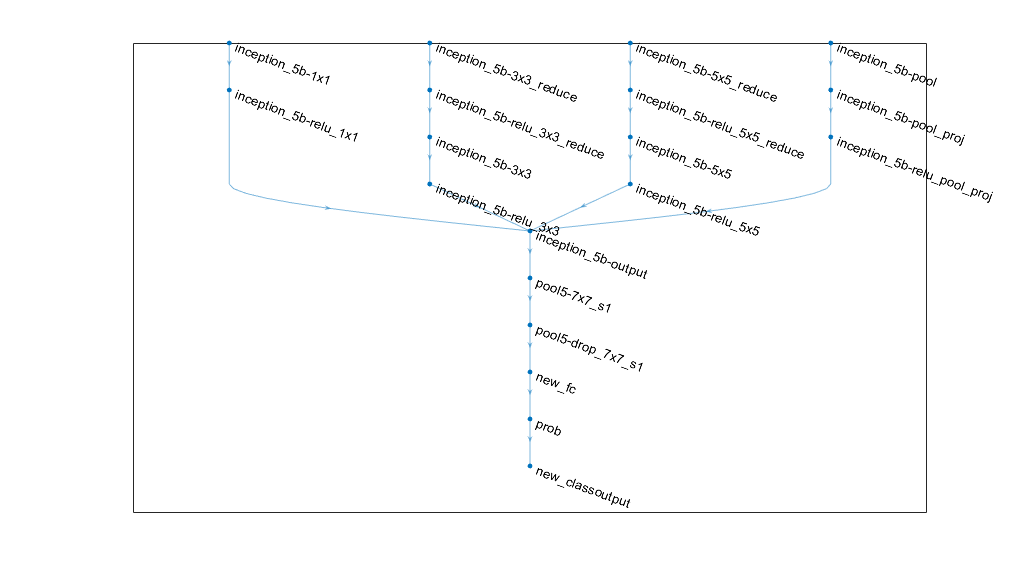

%Plotting the new classification layer
figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
plot(lgraph)
ylim([0,10])

%Learning Parameters
miniBatchSize = 16;
valFrequency = floor(numel(imgsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',6, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imgsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');

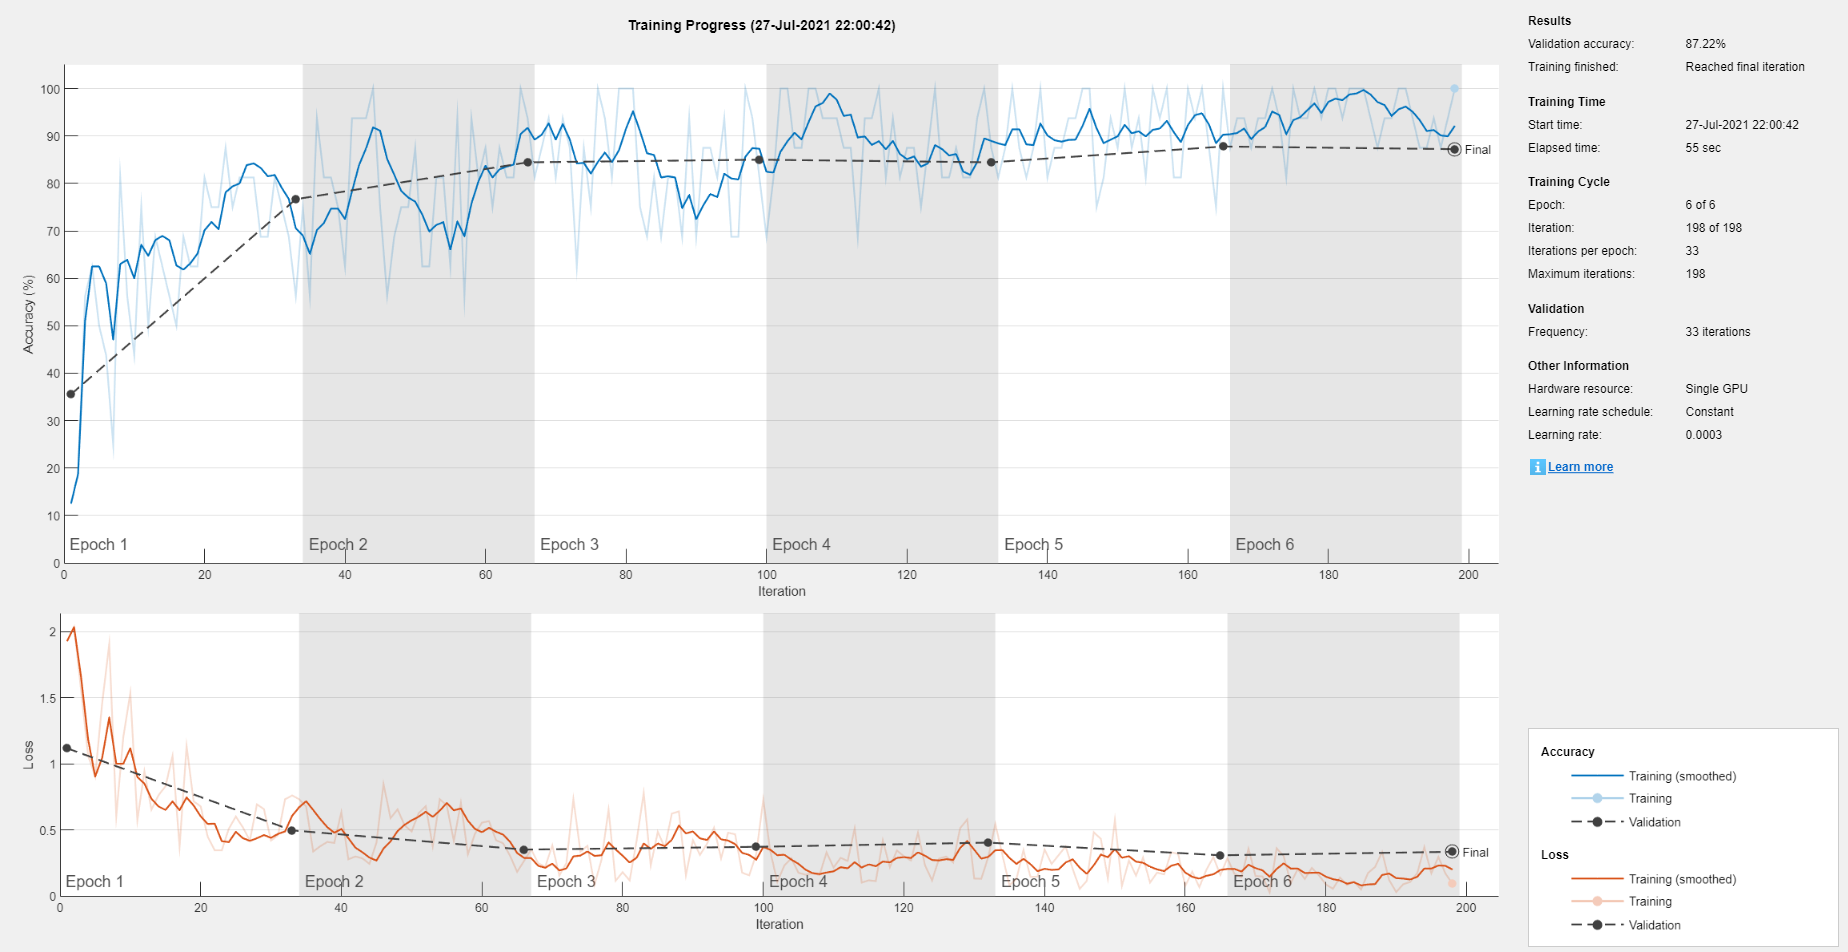

%Training the network
reset(gpuDevice())
net = trainNetwork(imgsTrain,lgraph,options);

%Classifying Test images
[YPred,probs] = classify(net,imgsTest);
accuracy = mean(YPred == imgsTest.Labels)

accuracy = 0.8667

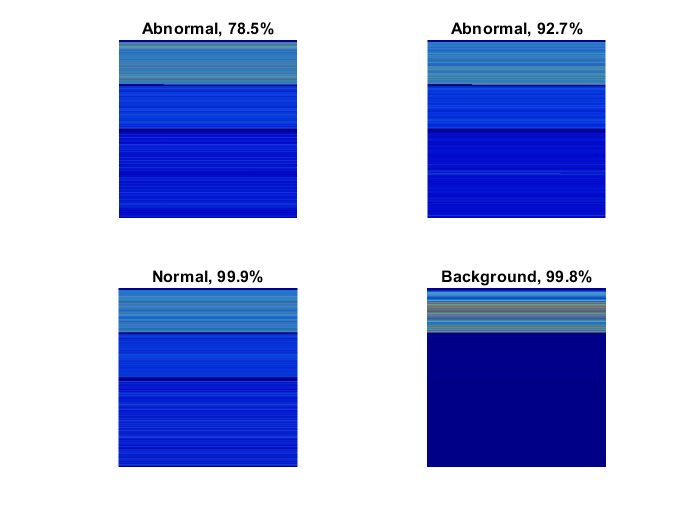

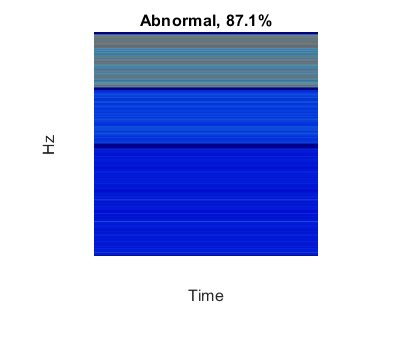

%Display four random test results
idx = randperm(numel(imgsTest.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imgsTest,idx(i));
    imshow(I)
    label = YPred(idx(i));
    title(string(label) + ", " + num2str(100*max(probs(idx(i),:)),3) + "%");
end

%Save the trained NN
save('net.mat', 'net');

% findLayersToReplace(lgraph) finds the single classification layer and the
% preceding learnable (fully connected or convolutional) layer of the layer
% graph lgraph.


function [learnableLayer,classLayer] = findLayersToReplace(lgraph)

if ~isa(lgraph,'nnet.cnn.LayerGraph')
    error('Argument must be a LayerGraph object.')
end

% Get source, destination, and layer names.
src = string(lgraph.Connections.Source);
dst = string(lgraph.Connections.Destination);
layerNames = string({lgraph.Layers.Name}');

% Find the classification layer. The layer graph must have a single
% classification layer.
isClassificationLayer = arrayfun(@(l) ...
    (isa(l,'nnet.cnn.layer.ClassificationOutputLayer')|isa(l,'nnet.layer.ClassificationLayer')), ...
    lgraph.Layers);

if sum(isClassificationLayer) ~= 1
    error('Layer graph must have a single classification layer.')
end
classLayer = lgraph.Layers(isClassificationLayer);


% Traverse the layer graph in reverse starting from the classification
% layer. If the network branches, throw an error.
currentLayerIdx = find(isClassificationLayer);
while true
    
    if numel(currentLayerIdx) ~= 1
        error('Layer graph must have a single learnable layer preceding the classification layer.')
    end
    
    currentLayerType = class(lgraph.Layers(currentLayerIdx));
    isLearnableLayer = ismember(currentLayerType, ...
        ['nnet.cnn.layer.FullyConnectedLayer','nnet.cnn.layer.Convolution2DLayer']);
    
    if isLearnableLayer
        learnableLayer =  lgraph.Layers(currentLayerIdx);
        return
    end
    
    currentDstIdx = find(layerNames(currentLayerIdx) == dst);
    currentLayerIdx = find(src(currentDstIdx) == layerNames);
    
end



end